# SectionB: PCA

## **Q1:**

### **a: covariance matrix, eigenvalues, and eigenvectors **

clear; clc; 
load("F1_PVT.mat");
% standarlize data
data = [];
for i = 1:size(F1_PVT,3)
    data = cat(1,data, F1_PVT(:,:,i));
end
data = normalize(data,1,'zscore');
covariance = cov(data);
[eig_V, eig_D] = eig(covariance)

eig_V =     0.5981   -0.3751   -0.7083
    0.5977   -0.3801    0.7059
    0.5340    0.8455    0.0032


eig_D =     0.5091         0         0
         0    1.1958         0
         0         0    1.2951


### **b: Replot the Standardised data with the Principal components displayed**

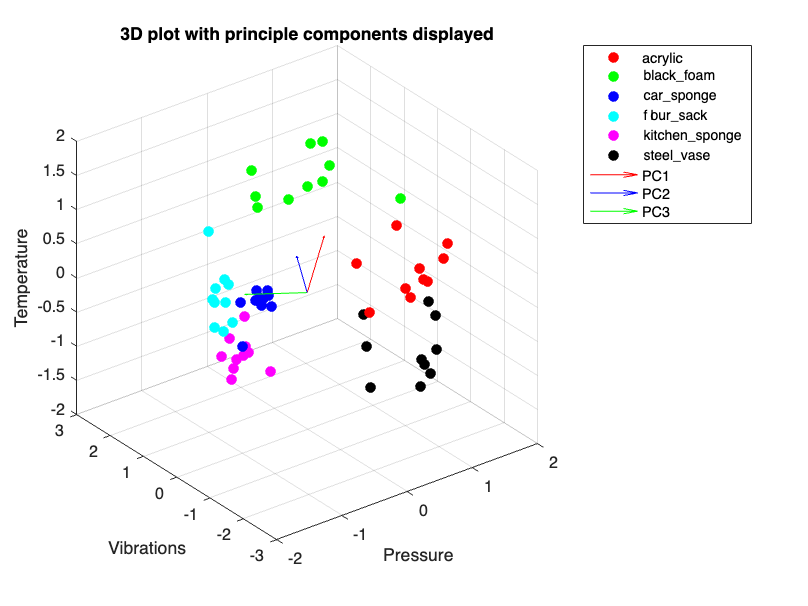

% replot
figure(1);
clf('reset');
colors = ["r", "g", "b", "c", "m", "k"];
str = ["acrylic","black\_foam","car\_sponge","flour\_sack","kitchen\_sponge","steel\_vase","PC1","PC2","PC3"];
for i = 1:size(data,1)/10
    x = data(10*(i-1)+1:10*i,1);
    y = data(10*(i-1)+1:10*i,2);
    z = data(10*(i-1)+1:10*i,3);
    plot3(x,y,z,'.','color',colors(i),'MarkerSize',20);
    hold on;
end

xlabel('Pressure');
ylabel('Vibrations');
zlabel("Temperature");
quiver3(0,0,0, eig_V(1,1),eig_V(2,1),eig_V(3,1),'red');
quiver3(0,0,0, eig_V(1,2),eig_V(2,2),eig_V(3,2),'blue');
quiver3(0,0,0, eig_V(1,3),eig_V(2,3),eig_V(3,3),'green');grid on;
legend(str);
title("3D plot with principle components displayed")
hold off;

### **c: Reduce the data to 2-dimensions and replot.**

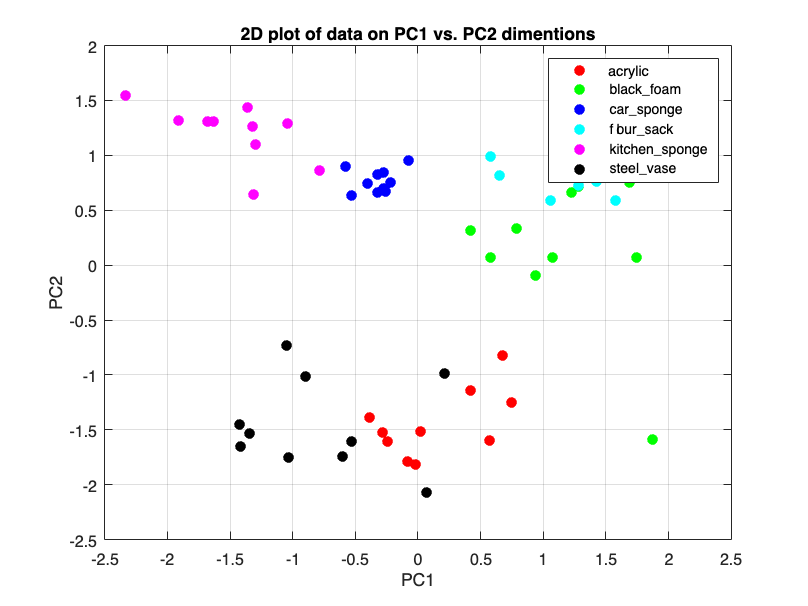

% eig_V = eig_V*eig_D;
figure(2);
clf('reset');
str = ["acrylic","black\_foam","car\_sponge","flour\_sack","kitchen\_sponge","steel\_vase"];
reduced_data = data*eig_V(:,2:3);

for i = 1:size(reduced_data,1)/10
    x = reduced_data(10*(i-1)+1:10*i,1);
    y = reduced_data(10*(i-1)+1:10*i,2);
    plot(x,y,'.','color',colors(i),'MarkerSize',20);
    hold on;
end

grid on;
legend(str);
xlabel("PC1");
ylabel("PC2");
title("2D plot of data on PC1 vs. PC2 dimentions")
hold off;

### **d: Show how the data is distributed across all principal components by plotting as separate 1D number lines.**

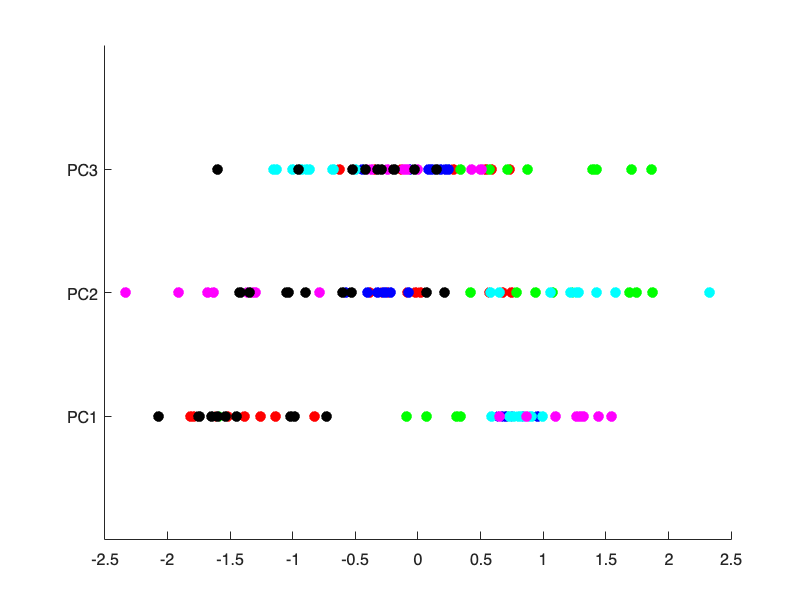

figure(3);
clf('reset');
pc1 = data*eig_V(:,3);
pc2 = data*eig_V(:,2);
pc3 = data*eig_V(:,1);
hold on;
ylim([0, 20]);
yticks([5 10 15]);
for i = 1:size(reduced_data,1)/10
    plot(pc1(10*(i-1)+1:10*i),5,'.','color',colors(i),'MarkerSize',20);
    plot(pc2(10*(i-1)+1:10*i),10,'.','color',colors(i),'MarkerSize',20);
    plot(pc3(10*(i-1)+1:10*i),15,'.','color',colors(i),'MarkerSize',20);
end

set(gca,'yticklabel',{"PC1","PC2","PC3"});
hold off;

## **S Q2:**

### **a: Use PCA to determine the principal components of the electrode data**

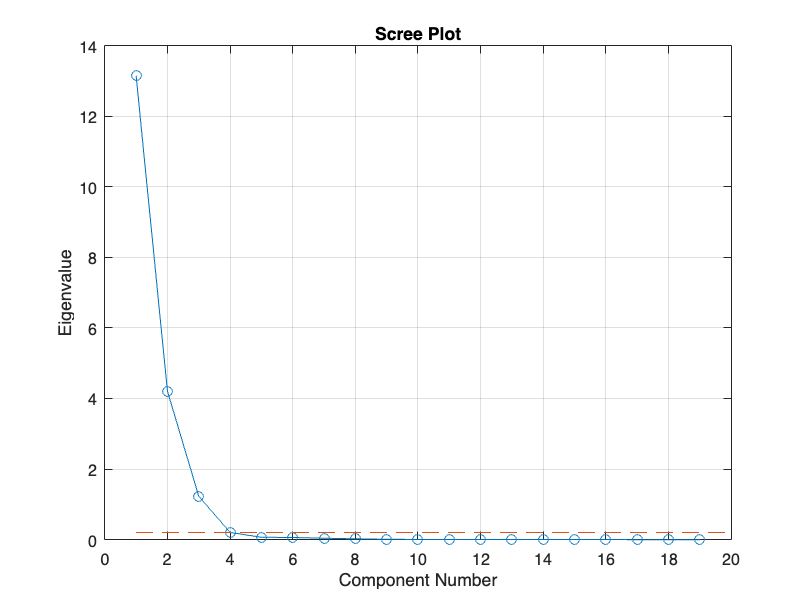

figure(4);
clf('reset');
load("F1_E.mat");
load("F1_PVT.mat");
% standarlize data
data = [];
for i = 1:size(F1_E,3)
    data = cat(1,data, F1_E(:,:,i));
end
data = normalize(data,1,'zscore');
covariance = cov(data);
[eig_V, eig_D] = eig(covariance);
variance = diag(eig_D);
variance = sort(variance, "descend");
figure(4);
plot(variance,'-o');
% xticks(1:1:20);
hold on;
plot(repelem(variance(4),20),'--');
xlabel("Component Number");
ylabel("Eigenvalue");
title("Scree Plot");
grid on;
hold off;

### **b: Visualize the electrode data using the three principal components with largest variance.**

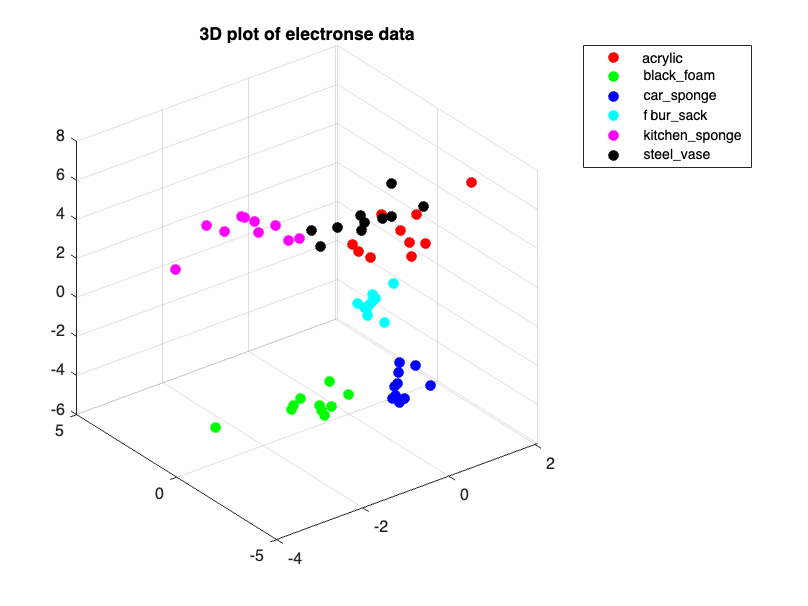

figure(5);
clf('reset');
reduced_data = data*eig_V(:,17:19);
colors = ["r", "g", "b", "c", "m", "k"];
for i = 1:size(data,1)/10
    x = reduced_data(10*(i-1)+1:10*i,1);
    y = reduced_data(10*(i-1)+1:10*i,2);
    z = reduced_data(10*(i-1)+1:10*i,3);
    plot3(x,y,z,'.','color',colors(i),'MarkerSize',20);
    hold on;
end
grid on;
legend(str);
title("3D plot of electronse data")
hold off;

save("./F1_E_3D.mat", "reduced_data")
